# LIVE SCRIPT FOR CALCULATING THE GLOBAL STIFFNESS MATRIX/FORCE

clc;
clear;


## Initialize Element Values

data.E = 70000;
data.v = 0.33;
data.D = D_matrix_Stress(data); 
data.nDOFPNode = 2;
% data.f=[3;3;0;5];
data.thikness= 0.3;
data.f=[0;0;0;0];


## Define connectivityMatrix and allNodalLocations


[data.GlobalNodes, data.Connectivity, data.EdgeNodes]=ReadABQINPFile("Job-25.txt");
data.nTotalDOF = size(data.GlobalNodes, 1) * data.nDOFPNode;
data.numElements = size(data.Connectivity, 1);
data.Total_corner_nodes=35;
data.top_corner_node=5;
data.bottom_corner_node=5;
data.mesh_size=0.5;
data.nNodes=4;
data.d=0.250;
data.updateNodalLocations=updateNodalLocations(data);

## Define Boundary Condition

data.BCnodes=[1;1;2;2;3;3;4;4;5;5;31;32;33;34;35];
data.BCDof=[2;1;2;1;2;1;2;1;2;1;2;2;2;2;2];
data.BC=[0;0;0;0;0;0;0;0;0;0;0.1;0.1;0.1;0.1;0.1];

## Create array to store structures that will calculate shape functions, Diff of shape functions, Elemental Stiffness matrices and surface force of the local element


elements_structure = create_elements_structure(data);


% function to assemble Global Stiffness and Global Force matrix 

Global_elements_structure=Global_Stifness_Matrix(@convert_to_index,elements_structure,data);

## calculate Global K and Global F with penalties

[K_Penalities,F_Penalties]=assemblyBC(data,Global_elements_structure);
Q = K_Penalities\F_Penalties;
Global_elements_structure.Q=Q;

Displacementandstraincalc = Displacementandstraincalc(Global_elements_structure,data);

## Plotting Results

[**Related documentation**](matlab:helpview('matlab','error_innerdim'))

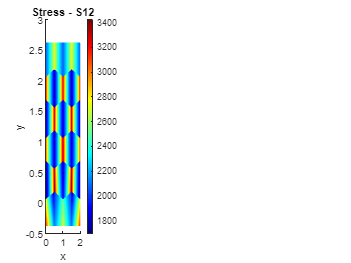


plot_Stress_Strain_Contours_Xi_Eta(Displacementandstraincalc,data);

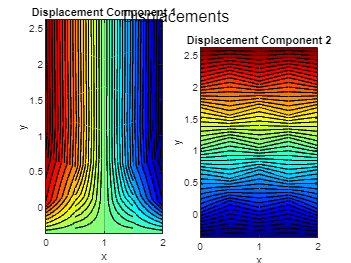

Displacement_plot(Displacementandstraincalc,data)

% figure 
% colormap('jet');
% imagesc(Global_elements_structure.Q)
% colorbar
% colormap('jet');
% imagesc(Global_elements_structure.K)
% colorbar
% colormap('jet');
% imagesc(K_Penalities)
% colorbar
% colormap('jet');
% imagesc(Global_elements_structure.F)
% colorbar
% colormap('jet');
% imagesc(F_Penalties)
% colorbar